## Using the PDE Toolbox

  
$${\nabla^2 p(x, t) - \frac{1}{c^2} \frac{\partial^2 p(x, t)}{\partial t^2} + \alpha\frac{\partial p(x,t)}{\partial t}= 0}$$
   
$$(\star)$$


Partial Differential Equation Toolbox solvers address equations of the form


$$m\frac{\partial^2u}{\partial t^2} + d\frac{\partial u}{\partial t} - \nabla(c\nabla u) + au = f$$


In the case of Equation $(\star)$, that is

$m = -\frac{1}{c_1^2}$,   in soft tissue region

$m = -\frac{1}{c_2^2}$,   in amniotic fluid region

 $d=\alpha$,    $c = -1$,    $a = 0$     and    $f=0$

c_SoftTissue = 1540;     % m/s
c_AmnioticFluid = 1510;  % m/s
dt1 = 26*10^(-6);        % s
dt2 = 100*10^(-6);       % s
L1 = c_SoftTissue*dt1/2*100;           % cm
L2 = c_AmnioticFluid*(dt2-dt1)/2*100;  % cm
FetalDistance = L1+L2                  % cm

FetalDistance =    7.5890e+00

L = FetalDistance;  % cm
c1 = c_SoftTissue/100; % Speed of sound in tissue (cm/us)
c2 = c_AmnioticFluid/100; % Speed of sound in amniotic fluid (cm/us)
alpha = 0; % Attenuation coefficient

model = createpde(1);
R1 = [3,4,0,L1,L1,0,30,30,-0.75,-0.75]';
R2 = [3,4,L1,L,L,L1,30,30,-0.75,-0.75]';
gm = [R1,R2];
sf = "ST+AF";
ns = char('ST','AF')

ns = 2×2 char array
    'ST'
    'AF'

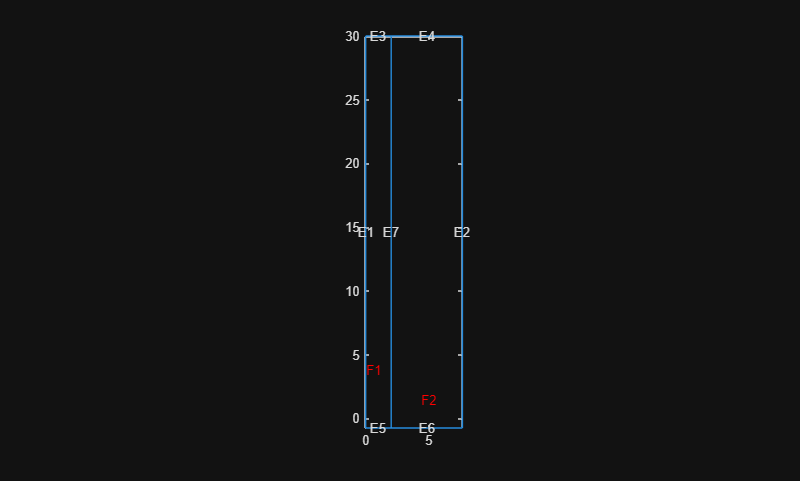

ns = ns';
g = decsg(gm,sf,ns);
geometryFromEdges(model,g);
% Show geometry
pdegplot(model,"EdgeLabels","on","FaceLabels","on")

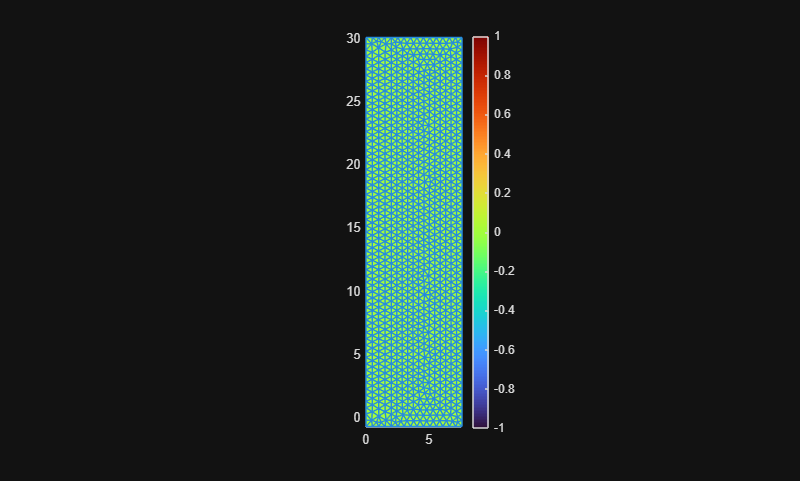

mfun = @(location,state) c1.*(location.x <= 2) + c2.*(location.x > 2);
%specifyCoefficients(model,"m",c1,"d",alpha,"c",-1,"a",0,"f",0, "Face",1);
%specifyCoefficients(model,"m",c2,"d",alpha,"c",-1,"a",0,"f",0, "Face",2);
specifyCoefficients(model,"m",mfun,"d",alpha,"c",-1,"a",0,"f",0);

applyBoundaryCondition(model,"neumann","Edge",[3:6],"q",0);
applyBoundaryCondition(model,"neumann","Edge",1,"q",R_2);
% applyBoundaryCondition(model,"neumann","Edge",7);
applyBoundaryCondition(model,"neumann","Edge",2,"q",R_2);
IC = @(x,y) x<=y;
% u0 = @(location) [rectangularPulse(0,L1/2,location.x);zeros(size(location.x))];
u0 = @(location) IC(location.x,L1/2).*IC(abs(location.y-15),1);
setInitialConditions(model,u0,c1,"Face",1);
setInitialConditions(model,0,0,"Face",2);

% Show mesh
msh = generateMesh(model,Hmax=0.5);
pdeviz(msh);

tlist = linspace(0,2,800);
results = solvepde(model,tlist);

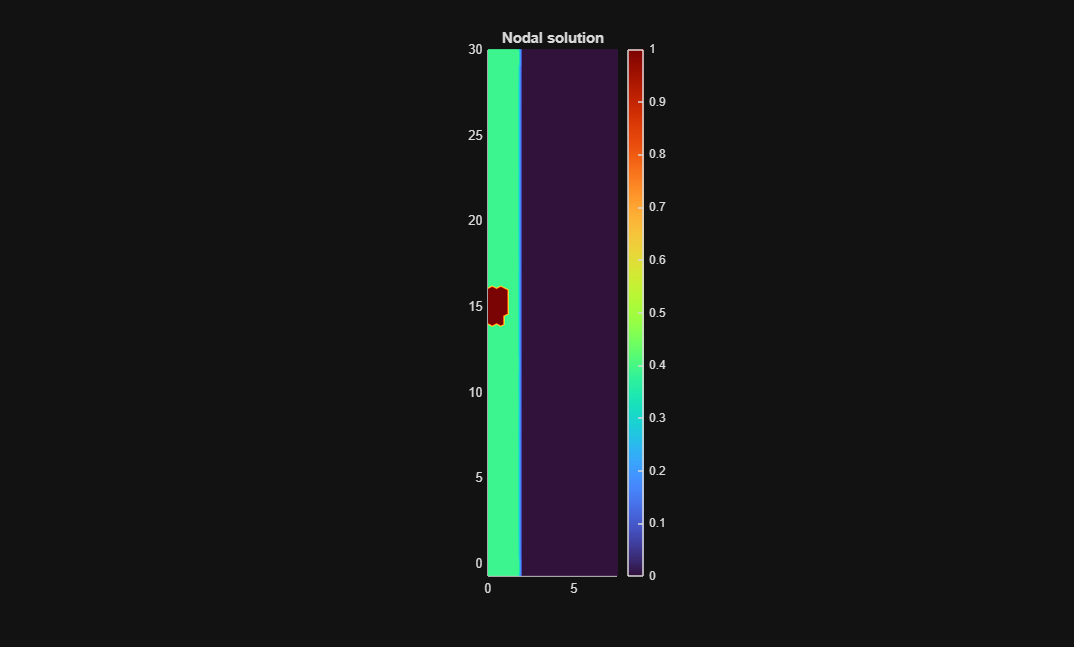

% Data to visualize
meshData = results.Mesh;
nodalData2 = results.NodalSolution(:,1);

% Create PDE result visualization
resultViz2 = pdeviz(meshData,nodalData2, ...
    "Title","Nodal solution", ...
    "ColorLimits",[0 1]);

% Animate
for ii = 1:200
    resultViz2.NodalData = results.NodalSolution(:,ii);
    pause(0.02)
end


% Clear temporary variables
clearvars meshData nodalData2 ii

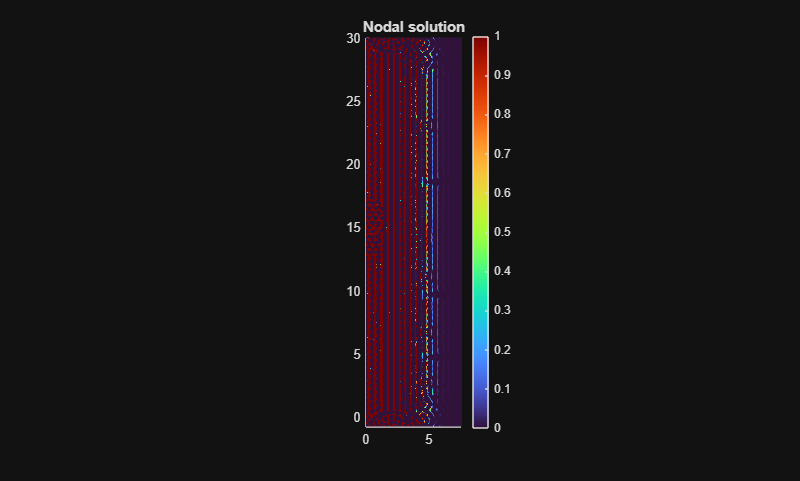

% Data to visualize
meshData = results.Mesh;
nodalData2 = results.NodalSolution(:,1);

% Create PDE result visualization
resultViz2 = pdeviz(meshData,nodalData2, ...
    "Title","Nodal solution", ...
    "YLimits",[14,16],...
    "ColorLimits",[0 1]);

% Animate
for ii = 1:800
    resultViz2.NodalData = results.NodalSolution(:,ii);
    drawnow
end